# Forecasting of coronavirus COVID19 epidemic (SIR model)

It is assumed that the model is a reasonable description of the one-stage epidemic. In particular, the model assumes a constant population, uniform mixing of the people, and equally likely recovery of infected. The model is data-driven, so its forecast is as good as data are. The forecasting change with new or changed data.

**DISCLAIMER**: Software and data is for education and not for medical or commercial. The model may fail in some situations. In particular, the model may be unadequate, the model may fail in the initial phase and in when additional epidemic stages or outbreaks  (not described by SIR model) are encountered. Use it at your own discretion.

**Source of data**

[https://ourworldindata.org/coronavirus-source-data.](https://ourworldindata.org/coronavirus-source-data.)

[https://www.worldometers.info/coronavirus/coronavirus-cases/#case-tot-outchina](https://www.worldometers.info/coronavirus/coronavirus-cases/#case-tot-outchina)

[https://en.wikipedia.org/wiki/2019%E2%80%9320_coronavirus_pandemic_by_country_and_territory](https://en.wikipedia.org/wiki/2019%E2%80%9320_coronavirus_pandemic_by_country_and_territory)

An actual source of data is for each country reported in the corresponding getData function.

An actual source of data is for each country reported in the corresponding getData function.

**Report**

fprintf('Date: %s\n',datestr(date))  

Date: 25-Mar-2020


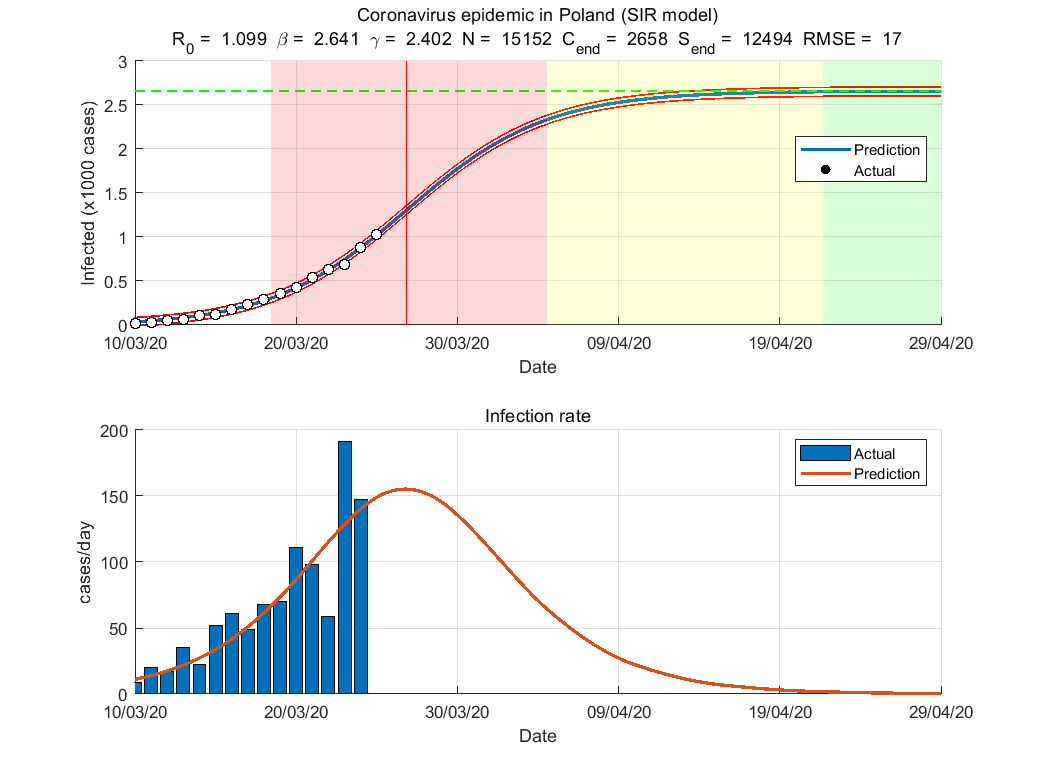

Epidemic modeling by susceptible-infected-recovered (SIR) model
  Country                       Poland
  Day                           22
Estimated the SIR model parameters
  Contact rate (beta)           2.641 (1/day)
  Removal rate (gamma)          2.402 (1/day)
  Population size (N)           15152
  Initial number of cases (I0)  1
Basic reproduction number (R0)  1.099
Final state
  Final number of cases         2658
  Final number of susceptibles  12493
Daily forcast for 26-Mar-2020
  Total                         1173
  Increase                      142
Estimated logistic model parameters
  Epidemic size (K)             2508 (cases)
  Epidemic rate (r)             0.238253 (1/day)
  Initial doubling time         2.9 (day)
Estimated duration (days)
  Turning day                   23
  Acceleration   phase          8 (days)
  Deaceleration  phsee          9 (days)
  Total duration                17 (days)
Estimated datums
  Outbreak                      04-Mar-2020
  Start of accele

aut = fitVirusCV19(@getDataPoland,'prn','on','nmax',1e5);